symss = settings;
%s.matlab.fonts.codefont.Size.TemporaryValue = 15;
s.matlab.fonts.editor.normal.Size.TemporaryValue = '20px';

**Momentum and free particle:**


$$E=\hbar \omega$$



$$p=\hbar k$$


In [mathematics](https://www.wikiwand.com/en/Mathematics), a **square-integrable function**, also called a **quadratically integrable function** or  **function**,[[1]](https://www.wikiwand.com/en/Square-integrable_function#citenote11) is a [real](https://www.wikiwand.com/en/Real_number)- or [complex](https://www.wikiwand.com/en/Complex_number)-valued [measurable function](https://www.wikiwand.com/en/Measurable_function) for which the [integral](https://www.wikiwand.com/en/Integral) of the square of the [absolute value](https://www.wikiwand.com/en/Absolute_value) is finite. Thus, square-integrability on the real line  is defined as follows.


$$f:\mathbb {R} \to \mathbb {C}\ square \ integrable  \ \leftrightarrow  \ \int_{-\infty}^{\infty}|f(x)|^{2}\,\mathrm {d} x<\infty}$$


Momentum operator:


$$P=-i\hbar \nabla$$



$$P |p>=p |p> \rightarrow P |k>=\hbar k |k>$$


## 
$$E=\frac{|p|^2}{2m} \rightarrow H=\frac{P^2}{2m}$$


Schrödinger equation for free particle:

## 
$$i\hbar \frac{\partial}{\partial t} \Psi (q,t)=-\frac{\hbar^2}{2m} \nabla^2\Psi (q,t)$$


**Group and Lie algebra of R:**

Theorem 10.1. Irreducible representations of $R$ are labeled by $c \in  C$ and given by

                                                 
$$\pi _c(a) = e^{ca}$$


Such representations are unitary (in U(1)) when c is purely imaginary.

## 
$$r=\pmatrix{0 & a \cr 0 &0} \rightarrow R=e^{cr}=\pmatrix{1 & ca \cr 0 & 1} \ \ @ c \in C, \ a \in R$$


Translation of the coordinates to $q^{'}=q+a$ induces a translation on function as $f(q-a)=f(q)-\frac{\partial f}{\partial q}a$ so the translation of the function is generated by $-\frac{\partial}{\partial q}$ which is the change of the function with respect to $q$, which is actually the momentum. Since $f(q-a)=f(q)-\frac{\partial f}{\partial q}a=e^{-a \partial_{i}}f(q)$ we may define momentum operator as $P_i=-\partial_i$ which is the Lie algebra of translation group. But since $(\partial_i)^\dagger =-\partial_i$ for spatial derivative, our group is unitary $((e^{-a \partial_i})^\dagger e^{-a \partial_i}=1)$, in this case $P_i$ would be anti-Hermitian.

We need Hermitian operators since their eigenvalues are real and can be used for observables. So we instead define momentum operator as $P_i=-i \partial_i$. But this is not enough, because of the Heisenberg uncertainty relation $([X,P]=i\hbar)$we define it as $P_i=-i \hbar \partial_i$. Lie algebra representation of this is $-\hbar \partial_i=-iP_i$ which is anti-Hermitian.

(Lagrangian has translational symmetry and this symmetry yields a value which does not change in time.)

From Schrödinger equation $(i \hbar \frac{d}{dt} |\Psi>=H|\Psi>)$ we see that $H$ is unitary since $((\frac{d}{dt})^\dagger=\frac{d}{dt})$ and since $i \hbar \frac{d}{dt} |\Psi>=H|\Psi> \rightarrow |\Psi(t)>=e^{-\frac{i}{\hbar}tH} |\Psi(0)>$

Since $U(t)=e^{-itH/ \hbar}$ is translate wavefunction in time, it is the time translation operator and since $<\Psi (t)|\Psi (t)>=<\Psi(0)|U(t)^\dagger U(t) |\Psi(0)>=<\Psi (0)|\Psi (0)>$, we know that $U(t)$ is unitary and its Lie algebra is anti-Hermitian. Lie algebra of this is $\frac{-iH}{\hbar}$ which is anti-Hermitian. 

## 
$$H|\Psi>=-\frac{\hbar^2}{2m}\nabla^2|\Psi>=E|\Psi>$$


## 
$$\Psi_E(q)=e^{i \sqrt{2mE}q/\hbar}=e^{ipq/\hbar}=e^{ikq} \rightarrow <q|k>=\frac{1}{\sqrt{2\pi}}{e^{ikq}$$



$$\rightarrow E=\frac{\hbar^2 k^2}{2m}$$


## 
$$<q|\Psi>=\sum_E <q|E><E|\Psi>=\sum_E e^{ikq}<E|\Psi>$$


## 
$$<q|\Psi(t)>=<q|\Psi> e^{-itE/\hbar}=\sum_E e^{ikq}<E|\Psi>e^{-ithk^2/2m}$$


syms h x
P=@(F,x) -1i*h*diff(F,x);

# Fourier Analysis and the Free

# Particle:

Since $<k|k>=\int_{-\infty}^{\infty}<k|q><q|k> dq =\infty$

we are imposing a boundary condition and using $S^1$ instead of $R$ and define inner product as


$$<\Psi_1|\Psi_2>=C\int_0^{2\pi} <\Psi_1|\phi><\phi|\Psi_2>d\phi$$


Since $<\Psi_1|\Psi_1>=C\int_0^{2\pi} <\Psi_1|\phi><\phi|\Psi_1>d\phi=C\int_0^{2\pi} 1 \  d\phi=2 \pi C \rightarrow C=\frac{1}{2\pi}$

Since on $S^1$ translation is defined by $SO(2)$


$$\phi \rightarrow \phi+\theta$$



$$\Psi(\phi) \rightarrow \Psi(\phi - \theta)$$


Translation generator becomes $-\frac{d}{d\phi}$

So we define momentum operator as

## 
$$P=-i\hbar \frac{d}{d\phi} \rightarrow P|n>=\hbar n |n> \rightarrow <\phi|n>=e^{in\phi} \rightarrow <n|m>=\delta_{nm}$$


syms n m t real
%m=1;n=1;
f1=exp(1i*n*t)

$$f1 = {\mathrm{e}}^{n\,t\,\mathrm{i}}$$

f2=exp(1i*m*t)

$$f2 = {\mathrm{e}}^{m\,t\,\mathrm{i}}$$


simplify(int(f1'*f2,t,[0,2*pi]))

$$ans = -\frac{{\mathrm{e}}^{2\,\pi \,\left(m\,\mathrm{i}-n\,\mathrm{i}\right)}\,\mathrm{i}-\mathrm{i}}{m-n}$$

int(sin(t)*exp(-1i*t),[0 2*pi])

$$ans = -\pi \,\mathrm{i}$$

Schwartz space $S(R)$ of functions $\Psi$ such that the function and its derivatives fall off faster than any power at infinity. a good class of examples of elements of S(R) to keep in mind are products of polynomials and a Gaussian function.

**Fourier Transform:**

## 
$$\Psi(k)=\frac{1}{\sqrt{2\pi}} \int^{\infty}_{-\infty} e^{-ikq} \ \Psi(q) \ dq$$



$$<k|\Psi>=\int_{-\infty}^{\infty} <k|q><q|\Psi>dq$$


Fourier Inversion:

## 
$$\Psi(q)=\frac{1}{\sqrt{2\pi}} \int^{\infty}_{-\infty} e^{ikq} \ \Psi(k) \ dk$$



$$<q|\Psi>=\int_{-\infty}^{\infty} <q|k><k|\Psi>dk$$


**Plancherel Theorem:**


$$<\Psi|\Psi>= \int_{-\infty}^{\infty} <\Psi|q><q|\Psi> dq = \int_{-\infty}^{\infty} <\Psi|k><k|\Psi> dk$$



$$<q|\Psi>=\int_{-\infty}^{\infty} <q|q^{'}><q^{'}|\Psi>dq^{'}=\int_{-\infty}^{\infty} \delta(q-q^{'}) \Psi(q^{'})dq^{'}$$



$$\rightarrow \delta(q-q^{'})=<q|q^{'}>= \int_{-\infty}^{\infty}<q|k><k|q^{'}>dk=\frac{1}{2\pi}\int_{-\infty}^{\infty} e^{ik(q-q^{'}} dk$$


**Solutions of the Schrödinger equation in momentum space:**


$$i \frac{\partial}{\partial t} \Psi(q,t)=-\frac{1}{2m}\frac{\partial^2}{\partial q^2} \Psi(q,t)$$



$$\rightarrow i \frac{\partial}{\partial t} \int_{-\infty}^{\infty} <q|k><k|\Psi(t)> dk=-\frac{1}{2m}\frac{\partial^2}{\partial q^2} \int_{-\infty}^{\infty} <q|k><k|\Psi(t)> dk$$



$$\rightarrow  \int_{-\infty}^{\infty} <q|k>i \frac{\partial}{\partial t}<k|\Psi(t)> dk= \int_{-\infty}^{\infty} -<k|\Psi(t)> \frac{1}{2m}\frac{\partial^2}{\partial q^2}<q|k> dk$$



$$\rightarrow  \int_{-\infty}^{\infty} <q|k>i \frac{\partial}{\partial t}<k|\Psi(t)> dk= \int_{-\infty}^{\infty} -<k|\Psi(t)> \frac{1}{2m}\frac{\partial^2}{\partial q^2}<q|k> dk$$



$$\rightarrow  \int_{-\infty}^{\infty} <q|k>i \frac{\partial}{\partial t}<k|\Psi(t)> dk= \int_{-\infty}^{\infty} <k|\Psi(t)> \frac{k^2}{2m}<q|k> dk$$
            
$$@<q|k>=\frac{1}{\sqrt{2\pi}} e^{ikq}$$



$$\rightarrow  i \frac{\partial}{\partial t}<k|\Psi(t)> =  \frac{k^2}{2m} <k|\Psi(t)>$$



$$\rightarrow <k|\Psi(t)>=e^{-\frac{ik^2t}{2m}} <k|\Psi(0)>$$


Time-frequency Fourier Transform:


$$<\omega|\Psi(k)>=\int_{-\infty}^{\infty} <\omega|t><t|\Psi(k)>dt$$
            
$$@<w|t>=\frac{1}{\sqrt{2\pi}} e^{i\omega t}$$



$$=\frac{1}{\sqrt{2\pi}}\int_{-\infty}^{\infty} e^{i\omega t}e^{-\frac{ik^2t}{2m}} <k|\Psi(0)>dt$$



$$=\delta(\omega-\frac{k^2}{2m})\sqrt{2\pi}<k|\Psi(0)>$$
 

# Position and the Free Particle


$$Q|q>=q|q>$$



$$q\delta(q-q^{'})=q^{'}\delta(q-q^{'})$$



$$[Q,P]=i\hbar 1$$



$$<q|\Psi>=\int_{-\infty}^{\infty}<q|q^{'}><q^{'}|\Psi>dq^{'}=\int_{-\infty}^{\infty}\delta(q-q^{'})\Psi(q^{'})dq^{'}$$


 
$$<q|\Psi>=\int_{-\infty}^{\infty}<q|k><k|\Psi>dk=\frac{1}{\sqrt{2\pi}}\int_{-\infty}^{\infty}e^{ikq} \ \Psi(k)dk$$


**Eigenfunctions of momentum and position operators:**

$P: <k|k^{'}>=\delta(k-k^{'})$ on momentum space

    $<q|k^{'}>=\frac{1}{\sqrt{2\pi}}e^{ik^{'}q}$ on position space

$Q: <q|q^{'}>=\delta(q-q^{'})$ on position space

    $<k|q^{'}>=\frac{1}{\sqrt{2\pi}}e^{-ikq^{'}}$ on momentum space

syms x
a=.001;
f=exp(-a*x^2/2);
fp=FourierTransform(f,x)

$$fp = 10\,\sqrt{2}\,\sqrt{5}\,{\mathrm{e}}^{-500\,k^{2}}$$

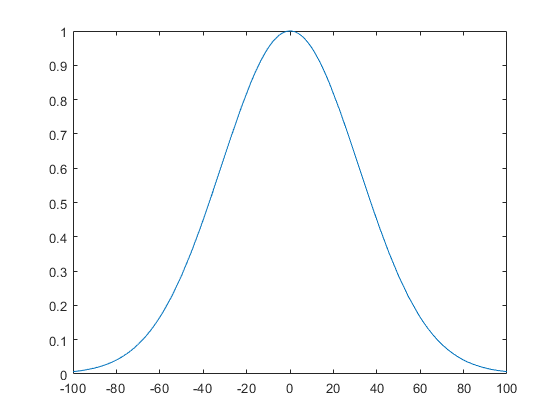

fplot(f,[-100 100])

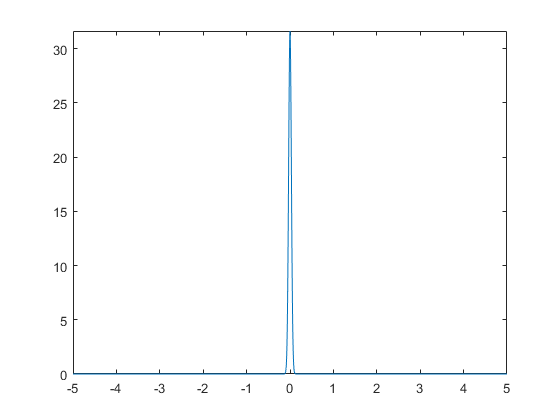

fplot(fp,[-5 5])

%ylim([0 1])


$$\lambda=\frac{2\pi}{k}$$



$$\omega=\frac{E}{\hbar}$$
  
$$@E=\frac{p^2}{2m}$$



$$|\Psi(t)>=U(t)|\Psi(0)> \rightarrow <k|\Psi(t)>=<k|U(t)|\Psi(0)>=e^{-ik^2 t/2m} <k|\Psi(0)>$$



$$<q|\Psi(t)>=<q|U(t)|\Psi(0)>=\int_{-\infty}^{\infty} <q|U(t)|q_0><q_0|\Psi(0)> dq_0$$


Propogator is $<q|U(t)|q_0>$ so


$$<q|U(t)|q_0>=\int_{-\infty}^{\infty}<q|k><k|U(t)|q_0> dk=\int_{-\infty}^{\infty}<q|k> e^{-ik^2 t/2m}<k|q_0> dk$$



$$=\frac{1}{2\pi} \int_{-\infty}^{\infty} e^{-ik^2 t/2m}e^{ik(q-q_0)}dk$$


$\int_{-\infty}^{\infty}$


$$<q|q^{'}><q^{'}|\Psi>$$


**\frac{1}{\sqrt{2\pi}}**

# **The Heisenberg group and the Schrödinger Representation**

Heisenberg Lie algebra


$$[X,Y]=Z, \  [X,Z]=[Y,Z]=0$$


[X Y Z H]=heisenberg(1)

$$X = \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$Y = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 1\\ 0 & 0 & 0 \end{array}\right)$$

$$Z = \left(\begin{array}{ccc} 0 & 0 & 1\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$H = \left(\begin{array}{ccc} 0 & x & z\\ 0 & 0 & y\\ 0 & 0 & 0 \end{array}\right)$$

syms a b c real
H2=a*X+b*Y+c*Z

$$H2 = \left(\begin{array}{ccc} 0 & a & c\\ 0 & 0 & b\\ 0 & 0 & 0 \end{array}\right)$$

commutator(H,H2)

$$ans = \left(\begin{array}{ccc} 0 & 0 & b\,x-a\,y\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

[X3 Y3 Z3 H3]=heisenberg(3)

X3 = 1×3 cell array
    {5×5 sym}    {5×5 sym}    {5×5 sym}


Y3 = 1×3 cell array
    {5×5 sym}    {5×5 sym}    {5×5 sym}


$$Z3 = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$H3 = \left(\begin{array}{ccccc} 0 & x_{1} & x_{2} & x_{3} & z\\ 0 & 0 & 0 & 0 & y_{1}\\ 0 & 0 & 0 & 0 & y_{2}\\ 0 & 0 & 0 & 0 & y_{3}\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

expm(H)

$$ans = \left(\begin{array}{ccc} 1 & x & z+\frac{x\,y}{2}\\ 0 & 1 & y\\ 0 & 0 & 1 \end{array}\right)$$

H+H2+1/2*commutator(H,H2)

$$ans = \left(\begin{array}{ccc} 0 & a+x & c+z-\frac{a\,y}{2}+\frac{b\,x}{2}\\ 0 & 0 & b+y\\ 0 & 0 & 0 \end{array}\right)$$

Since $e^A e^B = e^{A+B+\frac{1}{2}[A,B]+\frac{1}{12}[A,[A,B]]-\frac{1}{12}[B,[A,B]]+...$

and $[a,[b,c]]=0 \ \forall a,b,c \in h_3$


$$e^A e^B=e^{A+B+\frac{1}{2}[A,B]} \ \forall A,B,C \in h_3$$


Group law in exponenial coordinates become


$$AB=A+B+\frac{1}{2}[A,B]$$


(a*X)*(b*Y)

$$ans = \left(\begin{array}{ccc} 0 & 0 & a\,b\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

a*X+b*Y+1/2*commutator(a*X,b*Y)

$$ans = \left(\begin{array}{ccc} 0 & a & \frac{a\,b}{2}\\ 0 & 0 & b\\ 0 & 0 & 0 \end{array}\right)$$

**The Schrödinger representation of Heisenberg Lie Algebra:**


$$\Gamma_S^{'}(X)\Psi(q)=-iQ\Psi(q)=-iq\Psi(q)$$



$$\Gamma_S^{'}(Y)\Psi(q)=-iP\Psi(q)=-\frac{d}{dq}\Psi(q)$$



$$\Gamma_S^{'}(Z)\Psi(q)=-i\Psi(q)$$


Schrödinger representation, Lie group version in exponential coordinates:


$$e^{-iyP}e^{-ixQ}e^{-iz}=e^{-iz-iyP-ixQ+\frac{1}{2}[-iyP,-ixQ]}=e^{-iz}e^{ixy/2}e^{-iyP-ixQ}$$


This act on $\Psi(q)$ as


$$e^{-iz}e^{ixy/2}e^{-iyP-ixQ} \ \Psi(q)=e^{-iz}e^{ixy/2}e^{-ixq} \ \Psi(q-y)$$


# The Poisson Bracket and Symplectic Geometry

**Axiom** (States): The state of a classical mechanical system is given by a point in the phase space $M = R^{2d}$, with coordinates $q_j, p_j$, for $j = 1, . . . , d$.

**Axiom** (Observables): The observables of a classical mechanical system are the functions on phase space.

**Axiom** (Dynamics): There is a distinguished observable, the Hamiltonian function h, and states evolve according to Hamilton’s equations

    
$$\dot{q}_j=\frac{\partial h}{\partial p_j}$$
      
$$\dot{p}_j=-\frac{\partial h}{\partial q_j}$$


              
$$\downarrow$$
           
$$\downarrow$$



$$\frac{df}{dt}=\frac{\partial f}{\partial q}\frac{dq}{dt}+\frac{\partial f}{\partial p}\frac{dp}{dt}=\frac{\partial f}{\partial q}\frac{\partial h}{\partial p}-\frac{\partial f}{\partial p}\frac{\partial h}{\partial q}$$


**Poisson bracket:**


$$\{f1,f2\}=\frac{\partial f_1}{\partial q}\frac{\partial f_2}{\partial p}-\frac{\partial f_1}{\partial p}\frac{\partial f_2}{\partial q}$$



$$\downarrow$$
                            
$$\downarrow$$



$$\frac{df}{dt}=\{f,h\}$$
 
$$\rightarrow \dot{q}=\{q,h\}=\frac{\partial h}{\partial p}$$
     
$$\dot{p}=\{p,h\}=-\frac{\partial h}{\partial q}$$


 
$$h=\frac{p^2}{2m}+V(q) \rightarrow \dot{q}=\frac{p}{m} \ \ \dot{p}=-\frac{\partial V}{\partial q}$$


Poisson bracket is antisymmetric and has Jacobi identity property so it is actually a Lie algebra.

Leibniz rule:

$\{f_1f_2, f\} = \{f_1, f\}f_2 + f_1\{f_2, f\}$,


$$\{f, f_1f_2\} = \{f, f_1\}f_2 + f_1\{f, f_2\}$$


syms V(q) p m
f1=q^2;
f2=q*p;
f=poisson(f1,f2,1)

$$f = 2\,q^{2}$$

h=p^2/2/m+V;
poisson(p,h,1)

$$ans(q) = -\frac{\partial }{\partial q}V\left(q\right)$$

$\Omega(\cdot,\cdot)$ is the restriction of Poisson bracket to the linear functions on M such that 


$$f=c_q q+ c_p p+c=\pmatrix{\pmatrix{c_q \cr c_p} & c}$$


syms f1(q,p) f2(q,p)
syms cp cq c [1 2]
isequal(poisson(f1,f2,1),-poisson(f2,f1,1))

ans = logical
   1


f1=cq(1)*q+cp(1)*p+c(1);
f2=cq(2)*q+cp(2)*p+c(2);
poisson(f1,f2,1)

$$ans = {\mathrm{cp}}_{2}\,{\mathrm{cq}}_{1}-{\mathrm{cp}}_{1}\,{\mathrm{cq}}_{2}$$




syms q p [1 3]
f1=q(1)

$$f1 = q_{1}$$

f2=p(1)

$$f2 = p_{1}$$

poisson(f1,f2,3)

$$ans = 1$$


$$p \rightarrow \frac{\partial}{\partial q}$$
                
$$q \rightarrow -\frac{\partial}{\partial p}$$



$$X_f=\sum_{j=1}^{d} (\frac{\partial f}{\partial p_j}\frac{\partial}{\partial q_j}-\frac{\partial f}{\partial q_j}\frac{\partial}{\partial p_j})=-\{f,\cdot\}$$


syms q p
g=1/2*(q^2+p^2);
u=diff(g,p)

$$u = p$$

v=-diff(g,q)

$$v = -q$$

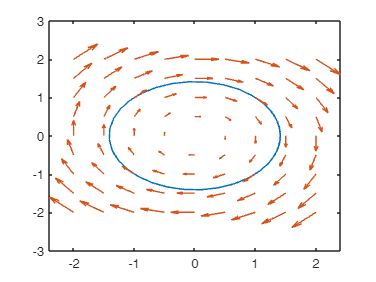



f=@(t,x) [x(2);
          -x(1)];
[t ya]=ode45(f,[0 10],[1 1]);
plot(ya(:,1),ya(:,2))
hold on
[X Y]=meshgrid(-2:.5:2);
U=subs(u,p,Y);
V=subs(v,q,X);
quiver(X,Y,U,V)
hold off

# Symplectic group

Symplectic group leave the symplectic matrices invariant.


$$Sp(2d,R)=\pmatrix{0 & I(d) \cr -I(d) & 0}$$



$$(\Omega c,\Omega c^{'})=(c,c^{'}) \rightarrow c^T \Omega^T Sp \Omega c^{'}=c^T Sp c^{'} \rightarrow \Omega^T Sp \Omega=Sp$$
 
$$@\Omega=e^{tL}$$


For d=1 case:

Sp=[0 1;-1 0];
syms O [2 2] real

eqn=transpose(O)*Sp*O==Sp

$$eqn = \left(\begin{array}{cc} 0=0 & O_{1,1}\,O_{2,2}-O_{1,2}\,O_{2,1}=1\\ O_{1,2}\,O_{2,1}-O_{1,1}\,O_{2,2}=-1 & 0=0 \end{array}\right)$$

So the condition is

eqn(1,2)

$$ans = O_{1,1}\,O_{2,2}-O_{1,2}\,O_{2,1}=1$$

which is actually a condition on the determinant $\Omega$:

det(O)

$$ans = O_{1,1}\,O_{2,2}-O_{1,2}\,O_{2,1}$$

So $Sp(2,R)=SL(2,R)$

Since $\Omega^T Sp \Omega=Sp \rightarrow \frac{d}{dt}(\Omega^T Sp \Omega)=0 \rightarrow \frac{d}{dt}((e^{tL})^T Sp \  e^{tL})=0$


$$\frac{d}{dt}((e^{tL})^T Sp \  e^{tL})=(e^{tL})^T (L^T \ Sp + Sp \ L) \  e^{tL}=0$$



$$@ t=0, \ L^T \ Sp +Sp \ L=0$$


So, Lie algebra of $\Omega=e^{tL}$ is for $d=1$


$$L=\pmatrix{a & b \cr c & -a}$$


syms a b c t real
L=[a,b;c,-a]

$$L = \left(\begin{array}{cc} a & b\\ c & -a \end{array}\right)$$

Basis of this Lie algebra $sp(2,R)=sl(2,R)$ is as follows:

E=diff(L,L(1,2))

$$E = \left(\begin{array}{cc} 0 & 1\\ 0 & 0 \end{array}\right)$$

expm(t*E);
F=diff(L,L(2,1))

$$F = \left(\begin{array}{cc} 0 & 0\\ 1 & 0 \end{array}\right)$$

expm(t*F);
G=diff(L,L(1,1))

$$G = \left(\begin{array}{cc} 1 & 0\\ 0 & -1 \end{array}\right)$$

expm(t*G);

Degree 2 polynomials are a 3 dimensional sub-Lie algebra with the basis


$$\frac{q^2}{2}$$
            
$$\frac{p^2}{2}$$
             
$$qp$$




syms q p
f1=q^2/2;
f2=-p^2/2;
f3=-q*p;
poisson(f1,f2,1)

$$ans = -p\,q$$

poisson(f3,f2,1)

$$ans = p^{2}$$

poisson(f3,f1,1)

$$ans = q^{2}$$


k=[q;p]

$$k = \left(\begin{array}{c} q\\ p \end{array}\right)$$

Isomorphism of the Lie algebra of degree 2 homogeneous polynomials to the Lie algebra of $sp(2,R)=sl(2,R)$is given by:


$$-aqp+\frac{bq^2}{2}-\frac{cp^2}{2}=\frac{1}{2} \pmatrix{q&p} \ L \ Sp^T \pmatrix{q \cr p}$$


So $L=\pmatrix{a & b \cr c& -a} \mapsto -aqp+\frac{bq^2}{2}-\frac{cp^2}{2}=\mu_L$

mL=simplify(1/2*transpose(k)*L*transpose(Sp)*k)

$$mL = -\frac{c\,p^{2}}{2}-a\,p\,q+\frac{b\,q^{2}}{2}$$

So we can identify basis elements as follows:


$$\frac{q^2}{2} \leftrightarrow E$$
            
$$-\frac{p^2}{2} \leftrightarrow F$$
        
$$-qp \leftrightarrow G$$



$$[E,F]=G$$
        
$$[G,E]=2E$$
        
$$[G,F]=-2F$$


mE=simplify(1/2*transpose(k)*E*transpose(Sp)*k)

$$mE = \frac{q^{2}}{2}$$

mF=simplify(1/2*transpose(k)*F*transpose(Sp)*k)

$$mF = -\frac{p^{2}}{2}$$

mG=simplify(1/2*transpose(k)*G*transpose(Sp)*k)

$$mG = -p\,q$$


isequal(commutator(E,F),G)

ans = logical
   1


isequal(commutator(G,E),2*E)

ans = logical
   1


isequal(commutator(G,F),-2*F)

ans = logical
   1


$L^T \ Sp +Sp \ L=0$ for $Sp(2d,R)$ $@ Sp=\pmatrix{0 & I(d) \cr -I(d) & 0}$

For $d=2$

Sp=sym([zeros(2),eye(2);
    -eye(2),zeros(2)])

$$Sp = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ -1 & 0 & 0 & 0\\ 0 & -1 & 0 & 0 \end{array}\right)$$

syms L [4 4]
syms a [1 4]
eqn=transpose(L)*Sp+Sp*L==0

$$eqn = \left(\begin{array}{cccc} 0=0 & L_{3,2}-L_{4,1}=0 & L_{1,1}+L_{3,3}=0 & L_{2,1}+L_{3,4}=0\\ L_{4,1}-L_{3,2}=0 & 0=0 & L_{1,2}+L_{4,3}=0 & L_{2,2}+L_{4,4}=0\\ -L_{1,1}-L_{3,3}=0 & -L_{1,2}-L_{4,3}=0 & 0=0 & L_{2,3}-L_{1,4}=0\\ -L_{2,1}-L_{3,4}=0 & -L_{2,2}-L_{4,4}=0 & L_{1,4}-L_{2,3}=0 & 0=0 \end{array}\right)$$

sol=solve(eqn,'ReturnConditions',true);
    
L=[sol.L1_1 sol.L1_2 a1 sol.L1_4;
     sol.L2_1 sol.L2_2 sol.L2_3 a2;
     a3 sol.L3_2 sol.L3_3 sol.L3_4;
     sol.L4_1 a4 sol.L4_3 sol.L4_4]

$$L = \left(\begin{array}{cccc} -z & -z_{1} & a_{1} & z_{2}\\ -z_{3} & -z_{4} & z_{2} & a_{2}\\ a_{3} & z_{5} & z & z_{3}\\ z_{5} & a_{4} & z_{1} & z_{4} \end{array}\right)$$

which is of the form


$$\pmatrix{A & B \cr C & -A^T}$$



syms F(q,p)
poisson(mL,F,1)

$$ans(q, p) = \left(a\,q+c\,p\right)\,\frac{\partial }{\partial q}F\left(q,p\right)-\left(a\,p-b\,q\right)\,\frac{\partial }{\partial p}F\left(q,p\right)$$

• $h_3$: the Lie algebra of linear polynomials on $M$, with basis$1, q, p$.

• $sl(2,R)$: the Lie algebra of order two homogeneous polynomials on $M$, with basis$q^2, p^2, qp$.

Taking all quadratic polynomials, we get a six-dimensional Lie algebra with basis elements $1, q, p, qp, q^2, p^2$. This is not the direct product of $h_3$ and $sl(2,R)$ since there are nonzero Poisson brackets

$\{qp,q\}=-q$,    $\{qp,p\}=p$

$\{\frac{p^2}{2},q\}=-p$,    $\{\frac{q^2}{2},p\}=q$